# Home Assignment 1

Autonomous Mobile Systems 2026/27

Name and surname: Jakob [dopolni priimek]

I declare that the work presented below is entirely my own and has been produced independently (enter YES or NO and add a comment if necessary): YES. Uporabljena pomoč AI je navedena spodaj.

I declare that I have accurately and correctly cited all content created using artificial intelligence tools (enter YES or NO and add a comment if necessary): YES.

List of artificial intelligence tools used (name and version): ChatGPT in OpenAI Codex (GPT-6).

Pri izdelavi naloge sem uporabljal ChatGPT kot pomoč pri razumevanju navodil, optimizaciji kode, ter pripravi grafov.

AI je pomagala tudi pri posplošitvi in implementaciji regulatorja, preverjanju rešitev ter pripravi razlage.

## Pogoji preizkusov

Stanje je q = [x; y; φ; γ], položaj je v metrih, kota v radianih. Zahtevana natančnost je 1 mm in 0,5°. Omejitvi hitrosti in pospeška vsakega prednjega kolesa sta 0,3 m/s in 1 m/s². Vsi primeri so bili preverjeni z merilnim šumom pri T = 0,01 s.

Poročilo za izris naloži že izračunane MAT-datoteke; pri Run All se simulacije ne ponavljajo in rezultati ne prepisujejo. Semena so navedena pri primerih. Na slikah so pot in končni obrisi, hitrosti koles ter zasuk γ. Polna črta hitrosti pomeni levo, črtkana desno kolo; barva označuje isto vozilo v vseh treh grafih. Legenda povezuje številko robota R s ciljem P.

Tabele podajajo zaporedno številko vozila, cilj P, čas [s], dolžino poti [m], končni napaki ed [mm] in eφ [°], največjo absolutno hitrost [m/s] in pospešek [m/s²] koles ter število vzorcev z zaznanim trkom. Napaki sta iz dejanskega končnega stanja simulatorja.

## 1. En robot

Regulator controlParking.m uporablja skupni parkingControl.m. Vozilo sledi premicam in krožnim lokom s predkrmiljenjem ukrivljenosti ter povratno vezavo prečne in kotne napake. Iz ukrivljenosti κ dobimo γref = atan(Dκ); pri izračunu ωs upoštevamo, da ωs = φ̇ + γ̇. Pred menjavo odseka se vozilo ustavi. Filtriranje meritev in počasnejši zaključni manever zmanjšata vpliv šuma.

Vodenje temelji na snovi 3_AMS_Control.pdf (prosojnice 10–11, 15–17 in 23). Izbor poti v parkingPlan.m je dodatek s hibridnim A*, povezanim z A* in Dijkstrovim postopkom iz 4_AMS_PathPlanning.pdf in 4a_AMS_Planiranje_poti_v_grafu.pdf. Pot upošteva celoten obris in ovire; po številkah parkirišč ni posebnih vej. Izvirni simulatorji so nespremenjeni.

Začetne lege: A = [0,3; 0,9; 0; 0], B = [0,9; 0,9; 0; 0], C = [0,4; 0,9; π; 0] in D = [0,8; 0,7; π/2; 0].

### 1.1 A → P11

Slika 1.1: pot, končne lege in vhodi. Tabela 1.1: rezultati vozil. Seme rng = 101.

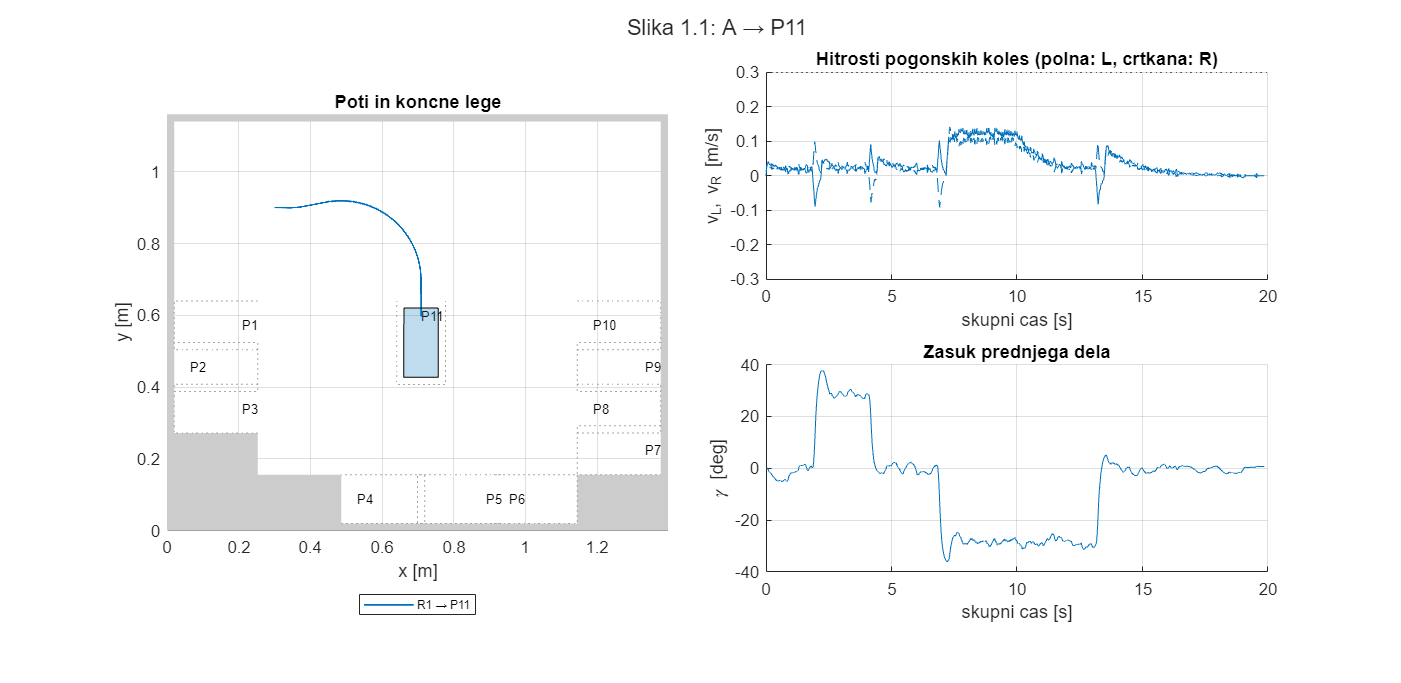

Tabela 1.1: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1       11     19.85    0.63667    0.49914    0.043014    0.14171         1         0  



prikaziPrimer('ex1case1.mat', false, '1.1', ...
    'A → P11');

### 1.2 B → P11

Slika 1.2: pot, končne lege in vhodi. Tabela 1.2: rezultati vozil. Seme rng = 102.

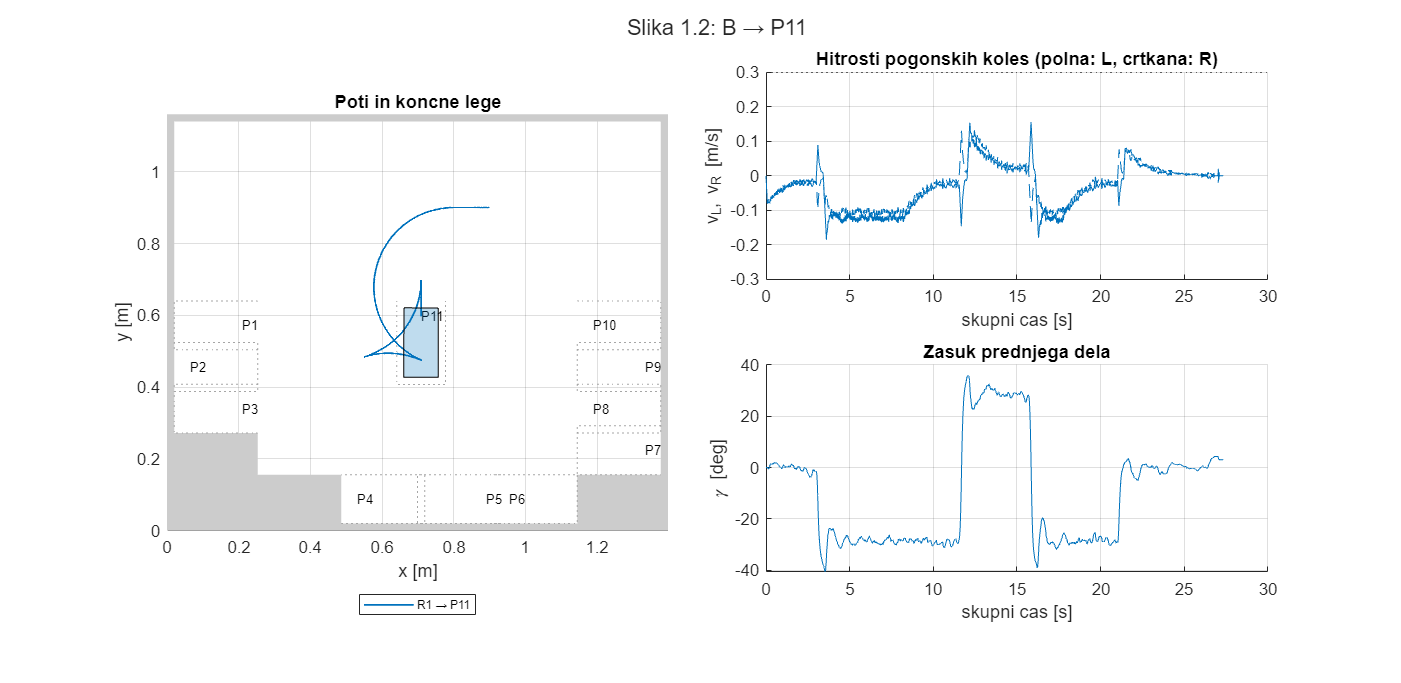

Tabela 1.2: rezultati parkiranja
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       11     27.33    1.2542    0.63603    0.083756    0.18534         1         0  



prikaziPrimer('ex1case2.mat', false, '1.2', ...
    'B → P11');

### 1.3 C → P11

Slika 1.3: pot, končne lege in vhodi. Tabela 1.3: rezultati vozil. Seme rng = 103.

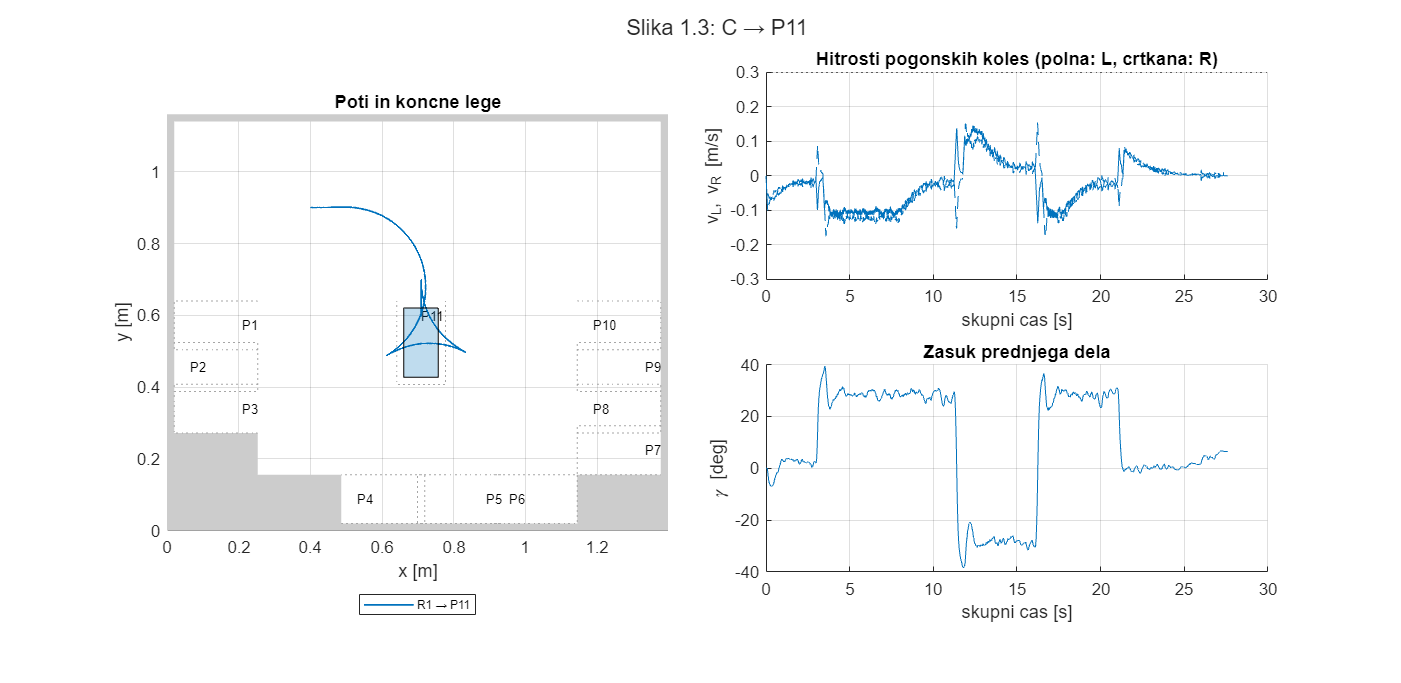

Tabela 1.3: rezultati parkiranja
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       11     27.59    1.2543    0.61319    0.072887    0.17484         1         0  



prikaziPrimer('ex1case3.mat', false, '1.3', ...
    'C → P11');

### 1.4 D → P11

Slika 1.4: pot, končne lege in vhodi. Tabela 1.4: rezultati vozil. Seme rng = 104.

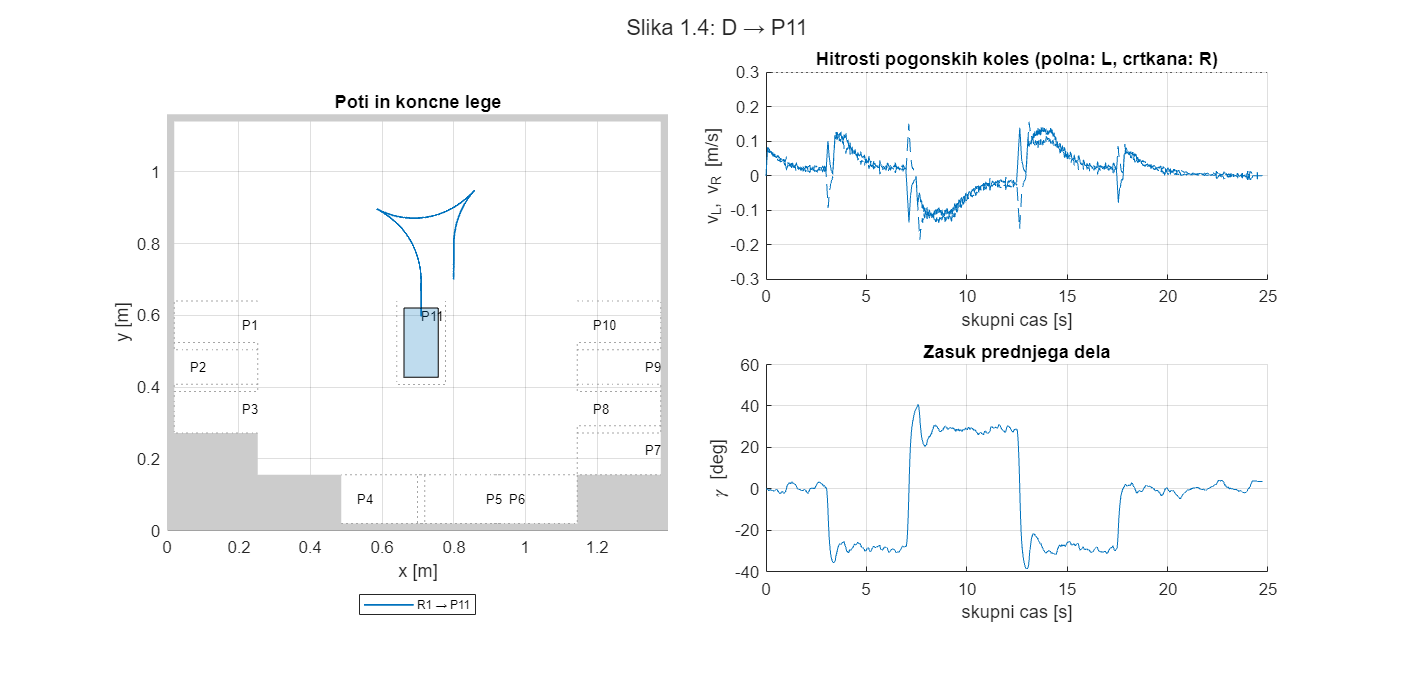

Tabela 1.4: rezultati parkiranja
    robot    cilj    cas_s     pot_m     ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    ______    ________    ________    _________    ____

      1       11     24.72    0.90225    0.4694    0.02727     0.18548         1         0  



prikaziPrimer('ex1case4.mat', false, '1.4', ...
    'D → P11');

### 1.5 A → P1

Slika 1.5: pot, končne lege in vhodi. Tabela 1.5: rezultati vozil. Seme rng = 105.

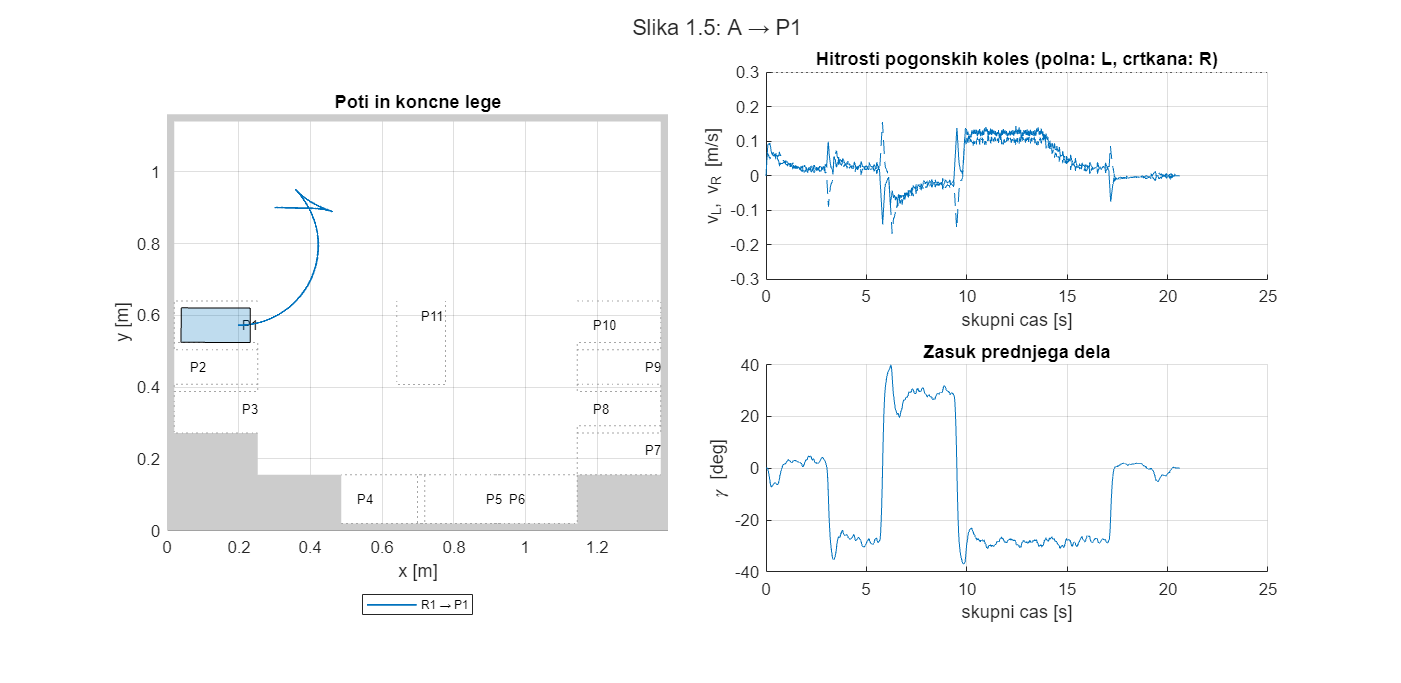

Tabela 1.5: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1       1      20.61    0.81513    0.63088    0.14846     0.16748         1         0  



prikaziPrimer('ex1case5.mat', false, '1.5', ...
    'A → P1');

### 1.6 A → P7

Slika 1.6: pot, končne lege in vhodi. Tabela 1.6: rezultati vozil. Seme rng = 106.

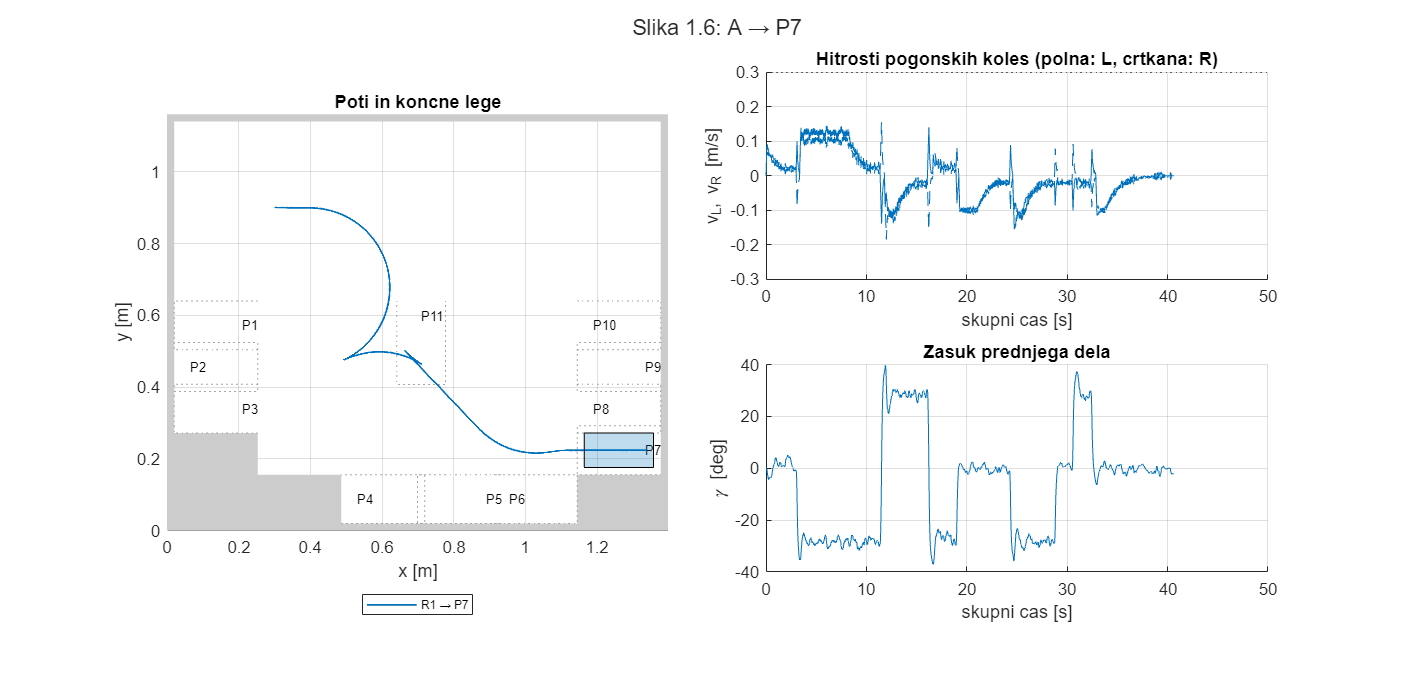

Tabela 1.6: rezultati parkiranja
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       7      40.61    1.7678    0.49928    0.022402     0.1848         1         0  



prikaziPrimer('ex1case6.mat', false, '1.6', ...
    'A → P7');

### 1.7 A → P5

Slika 1.7: pot, končne lege in vhodi. Tabela 1.7: rezultati vozil. Seme rng = 107.

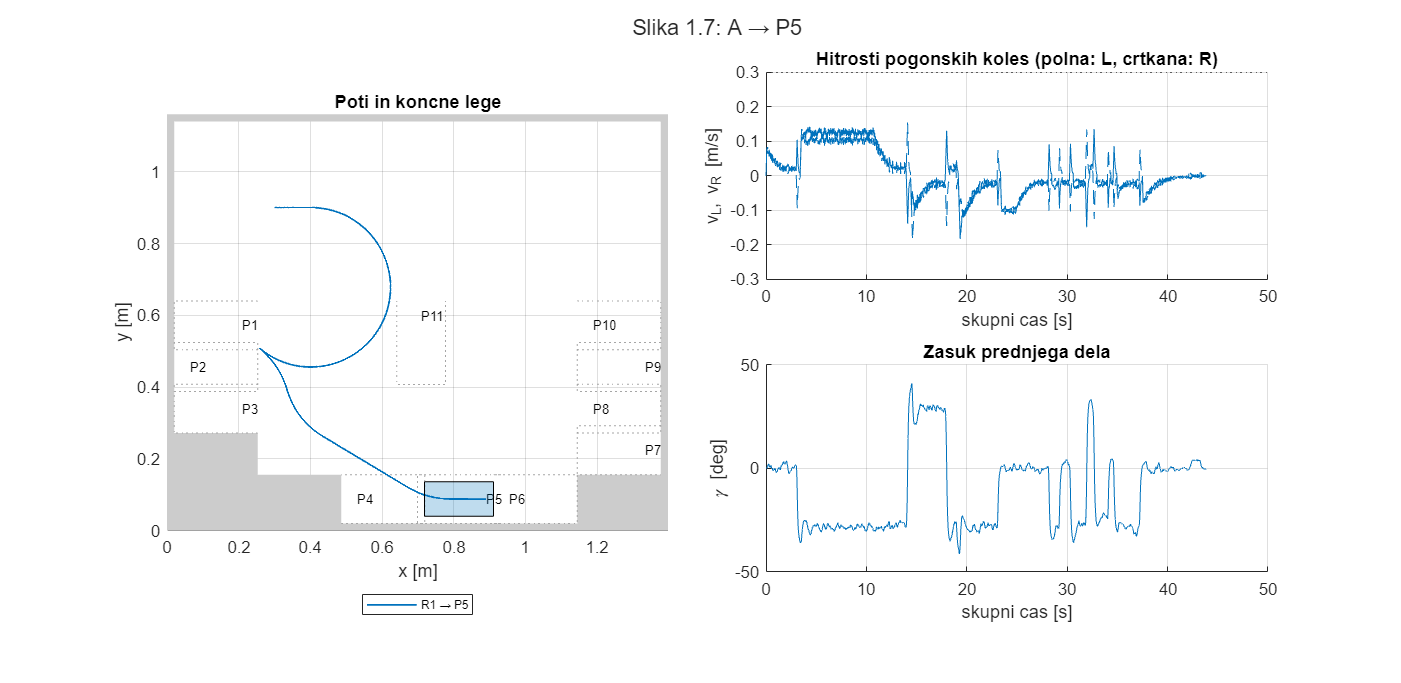

Tabela 1.7: rezultati parkiranja
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       5      43.86    1.7999    0.62622    0.027379     0.1858         1         0  



prikaziPrimer('ex1case7.mat', false, '1.7', ...
    'A → P5');

### 1.8 Naključna začetna lega in cilj

Slika 1.8: pot, končne lege in vhodi. Tabela 1.8: rezultati vozil. Seme rng = 401.

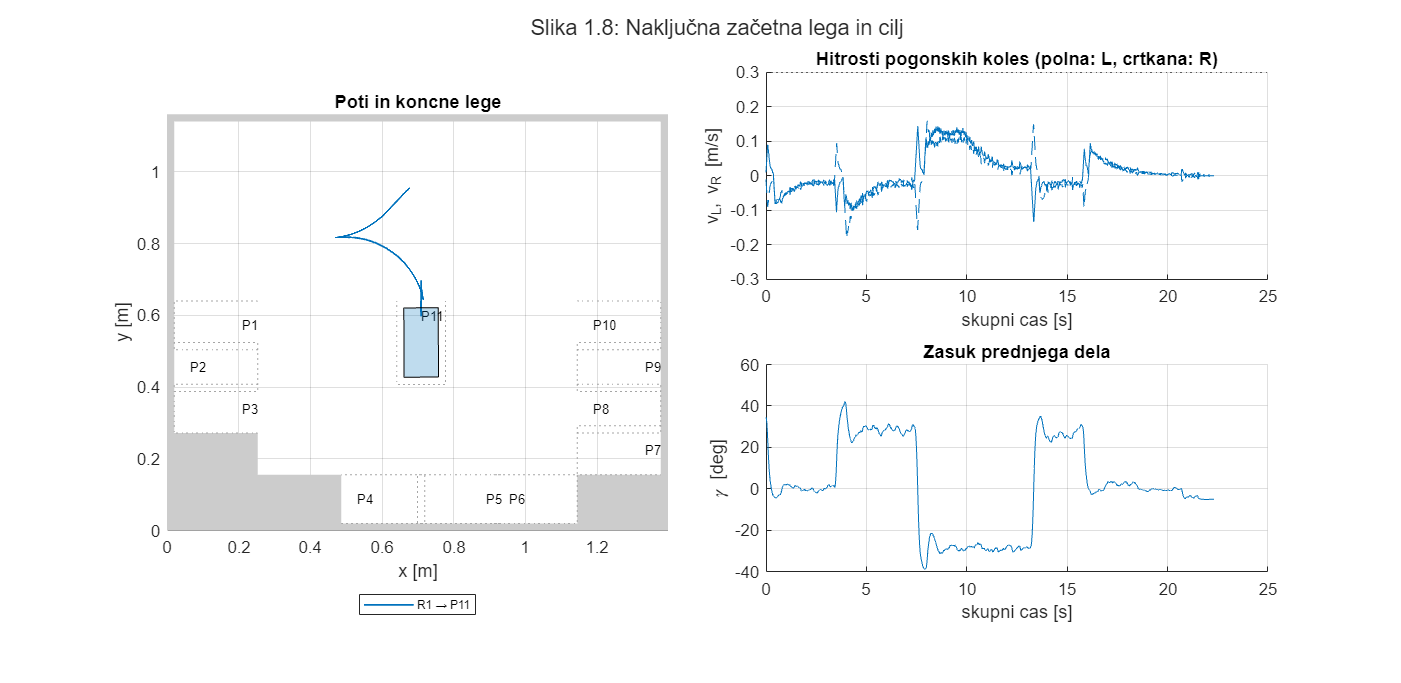

Tabela 1.8: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1       11     22.31    0.73468    0.73198     0.2164      0.1822         1         0  



prikaziPrimer('ex1random1.mat', false, '1.8', ...
    'Naključna začetna lega in cilj');

Uspešnih je vseh 8 parkiranj brez zaznanih trkov. Največji napaki sta 0,732 mm in 0,216°; najdaljše parkiranje traja 43,86 s. Zahtevi natančnosti in omejitvi koles sta izpolnjeni.

## 2. Več robotov

Roboti parkirajo zaporedno iz S = [0,6; 0,9; 0; 0]. Pred naslednjim robotom se stanje regulatorja ponastavi, parkirana vozila pa postanejo ovire. Uporabljena sta isti regulator in načrtovalnik kot pri prvi nalogi.

### 2.1 S → P1, P8, P10, P3, P6

Slika 2.1: pot, končne lege in vhodi. Tabela 2.1: rezultati vozil. Seme rng = 201.

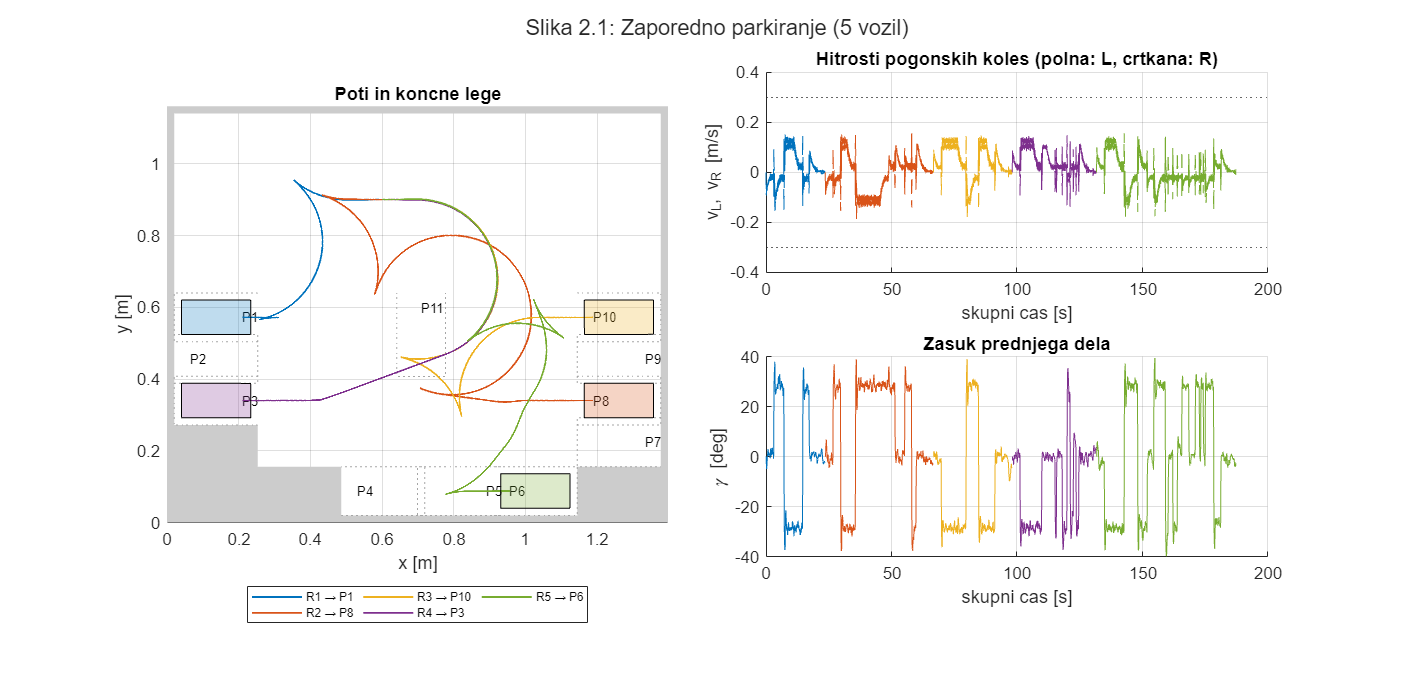

Tabela 2.1: rezultati parkiranja
    robot    cilj    cas_s    pot_m      ed_mm      ephi_deg     vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    __________    ________    _________    ____

      1        1     23.62    0.9056    0.58966    8.2899e-05    0.16675         1         0  
      2        8      43.1    2.0727    0.70163      0.021813    0.19019         1         0  
      3       10      31.4    1.6526    0.44849       0.19052    0.18489         1         0  
      4        3     33.57    1.3431    0.58923       0.18528    0.14792         1         0  
      5        6      55.7    1.9058    0.63267      0.093026    0.17744         1         0  



prikaziPrimer('ex2case1.mat', false, '2.1', ...
    'Zaporedno parkiranje (5 vozil)');

### 2.2 S → P2, P9, P7, P4

Slika 2.2: pot, končne lege in vhodi. Tabela 2.2: rezultati vozil. Seme rng = 202.

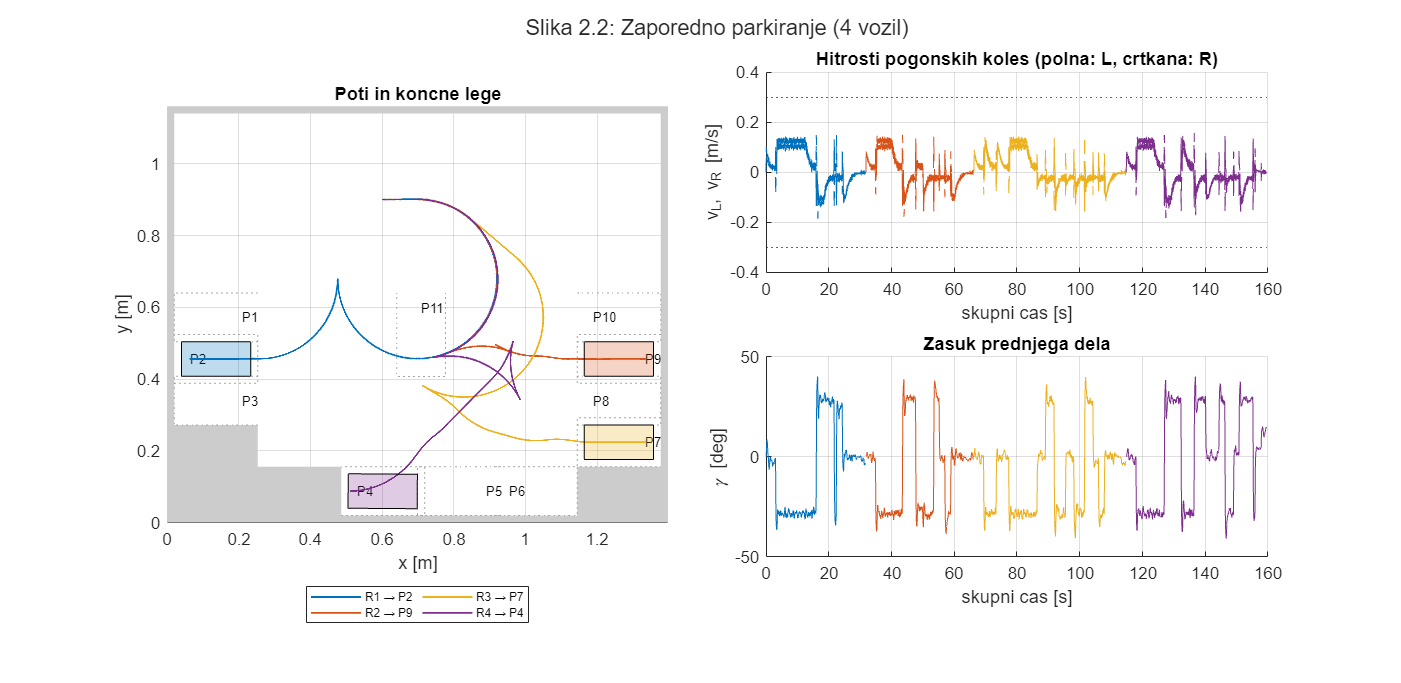

Tabela 2.2: rezultati parkiranja
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       2      31.85    1.6984    0.55923    0.031121    0.18527         1         0  
      2       9       34.4    1.3482    0.62277    0.046373    0.17813         1         0  
      3       7      48.59    1.7492    0.61261    0.045988    0.15691         1         0  
      4       4      44.74    1.8649    0.56113     0.38306    0.18319         1         0  



prikaziPrimer('ex2case2.mat', false, '2.2', ...
    'Zaporedno parkiranje (4 vozil)');

### 2.3 S → P1, P3, P10, P8, P6, P2, P7, P9, P4, P5

Slika 2.3: pot, končne lege in vhodi. Tabela 2.3: rezultati vozil. Seme rng = 203.

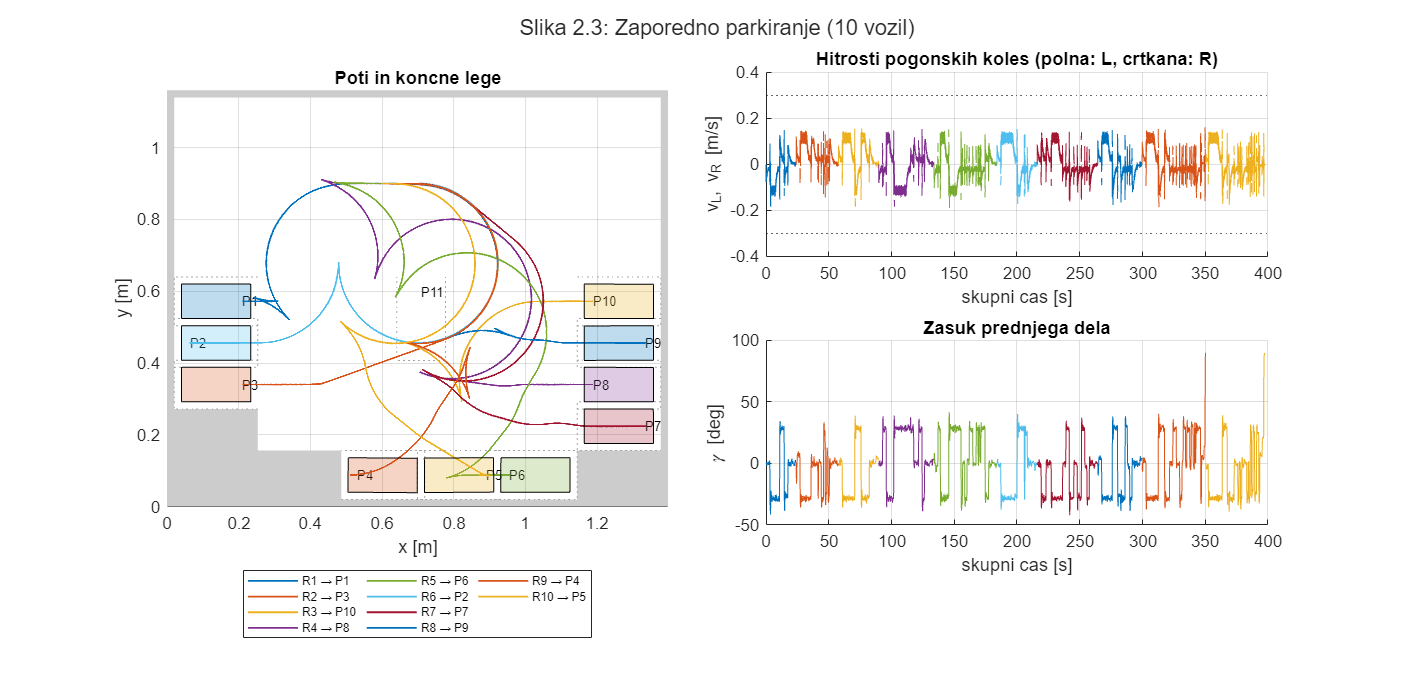

Tabela 2.3: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1        1     24.01    0.90577    0.43941    0.010638    0.18433         1         0  
      2        3     33.71     1.3451    0.55106     0.02253    0.14587         1         0  
      3       10     32.07     1.6545    0.44175    0.067917    0.18462         1         0  
      4        8     44.11     2.0763    0.62778    0.063988    0.18475         1         0  
      5        6      50.1     1.8453    0.40163    0.085946       0.19         1         0  
      6        2     32.11     1.7003    0.60188    0.087152    0.18948         1         0  
      7        7     48.22     1.7495    0.76272    0.078301    0.16195         1         0  
      8        9     35.33     1.3497    0.57521     0.19288    0.17741         1         0  
      9        4     50.95

prikaziPrimer('ex2case3.mat', false, '2.3', ...
    'Zaporedno parkiranje (10 vozil)');

### 2.4 S → P11, P1, P2, P9, P10, P5, P3, P8, P7, P4, P6

Slika 2.4: pot, končne lege in vhodi. Tabela 2.4: rezultati vozil. Seme rng = 204.

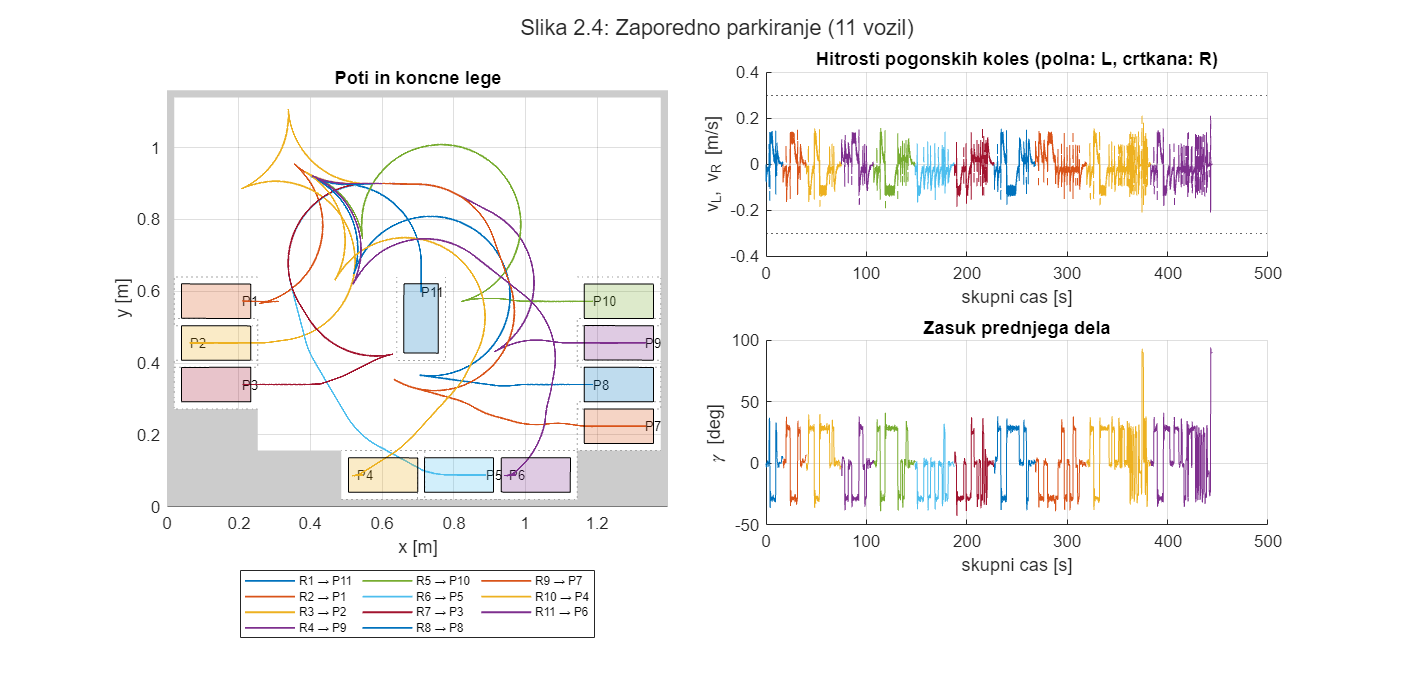

Tabela 2.4: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg     vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    _________    ________    _________    ____

      1       11     16.86    0.55311    0.72672      0.13348    0.15803         1         0  
      2        1     23.41    0.90441    0.62316      0.15928    0.17371         1         0  
      3        2     34.96     1.6811    0.54162      0.14464    0.18489         1         0  
      4        9     32.13     1.2204    0.61779      0.10154    0.17643         1         0  
      5       10     41.28     1.8073    0.52413        0.024    0.19135         1         0  
      6        5     39.18     1.3239    0.64634    0.0050542    0.16638         1         0  
      7        3      39.6     1.2995    0.62719     0.081153    0.18476         1         0  
      8        8     40.91     2.0194    0.65214      0.04581    0.17525         1         0  
      9        7

prikaziPrimer('ex2case4.mat', false, '2.4', ...
    'Zaporedno parkiranje (11 vozil)');

### 2.5 Naključne začetne lege in zaporedje vseh 11 ciljev

Slika 2.5: pot, končne lege in vhodi. Tabela 2.5: rezultati vozil. Seme rng = 501.

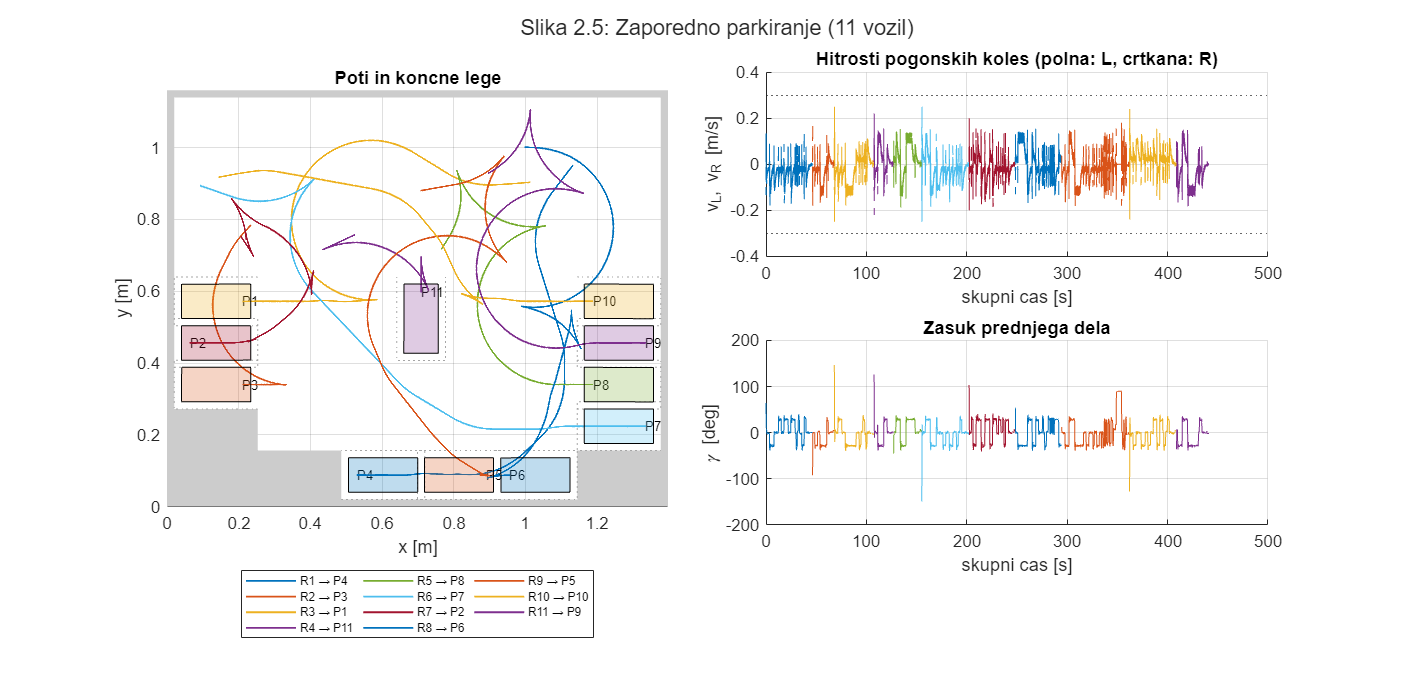

Tabela 2.5: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg     vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    _________    ________    _________    ____

      1        4     46.33     1.3628    0.73751      0.06366    0.17888         1         0  
      2        3     21.67    0.70494    0.72683      0.16868    0.18021         1         0  
      3        1     39.59     1.5607    0.67766     0.037006       0.25         1         0  
      4       11      19.5    0.64726      0.428     0.039115       0.22         1         0  
      5        8     28.01     1.3166    0.59163     0.084036    0.18778         1         0  
      6        7     47.15     1.7796    0.68025    0.0069049       0.25         1         0  
      7        2     46.11      1.196    0.63277     0.056381        0.2         1         0  
      8        6      46.1     1.6955    0.42836      0.16237    0.17938         1         0  
      9        5

prikaziPrimer('ex2random1.mat', false, '2.5', ...
    'Zaporedno parkiranje (11 vozil)');

Uspešnih je vseh 41 parkiranj brez zaznanih trkov. Največji napaki sta 0,763 mm in 0,412°; najdaljše parkiranje traja 67,57 s. Zahtevi natančnosti in omejitvi koles sta izpolnjeni.

## 3. Omejitev zasuka prednjega dela na ±30°

controlParkingLim.m uporabi isti regulator z γmax = π/6. Referenčni loki ustrezajo zasuku 28,5°, zato ostane rezerva za popravke do 30°. Obračanje na mestu nadomestijo manevri naprej in nazaj. Preverjena so ista zaporedja iz S kot pri drugi nalogi; črtkani vodoravni črti v grafu γ označujeta meji ±30°.

### 3.1 S → P1, P8, P10, P3, P6

Slika 3.1: pot, končne lege in vhodi. Tabela 3.1: rezultati vozil. Seme rng = 301.

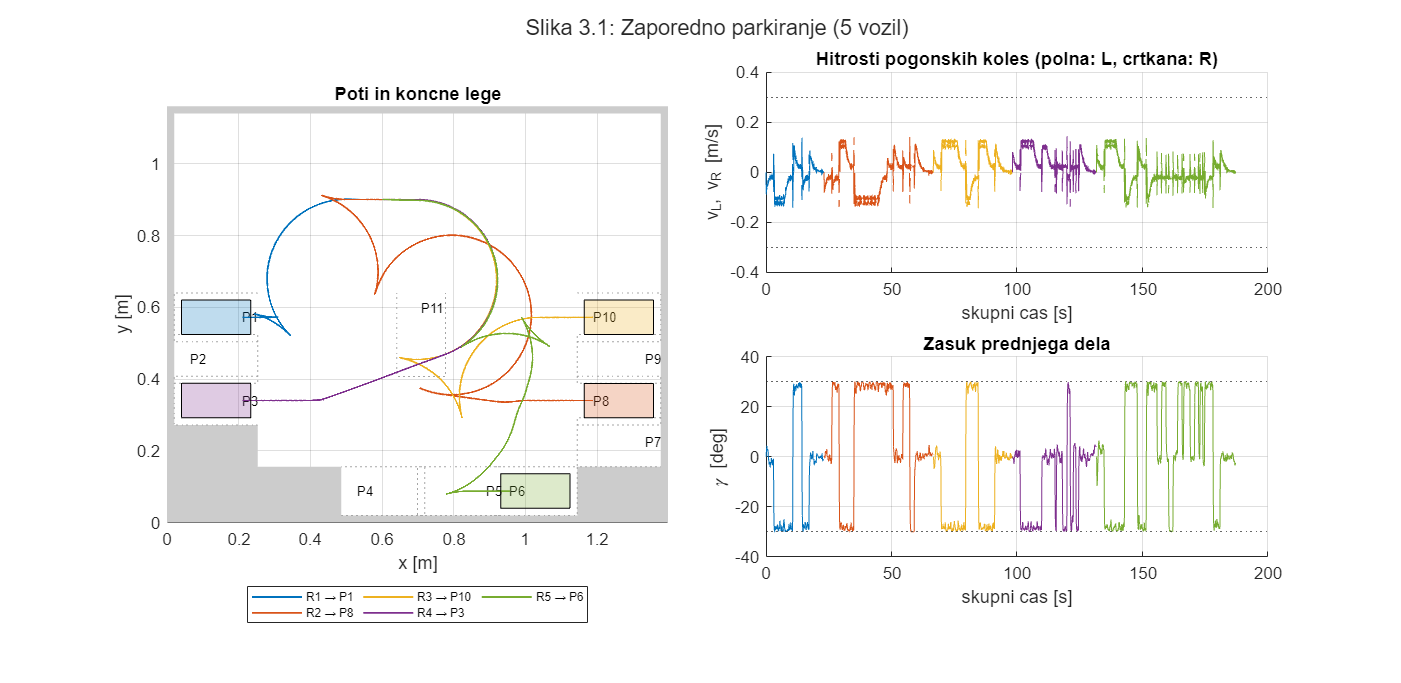

Tabela 3.1: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1        1     23.13    0.90232    0.70589    0.036579    0.14146         1         0  
      2        8     43.53      2.075    0.50528    0.010655    0.14071         1         0  
      3       10     31.51     1.6492    0.53572    0.018516    0.14392         1         0  
      4        3     33.46     1.3448    0.69215    0.049103    0.14332         1         0  
      5        6     55.66     1.8076    0.48562    0.051287    0.14236         1         0  



prikaziPrimer('ex3case1.mat', true, '3.1', ...
    'Zaporedno parkiranje (5 vozil)');

### 3.2 S → P2, P9, P7, P4

Slika 3.2: pot, končne lege in vhodi. Tabela 3.2: rezultati vozil. Seme rng = 302.

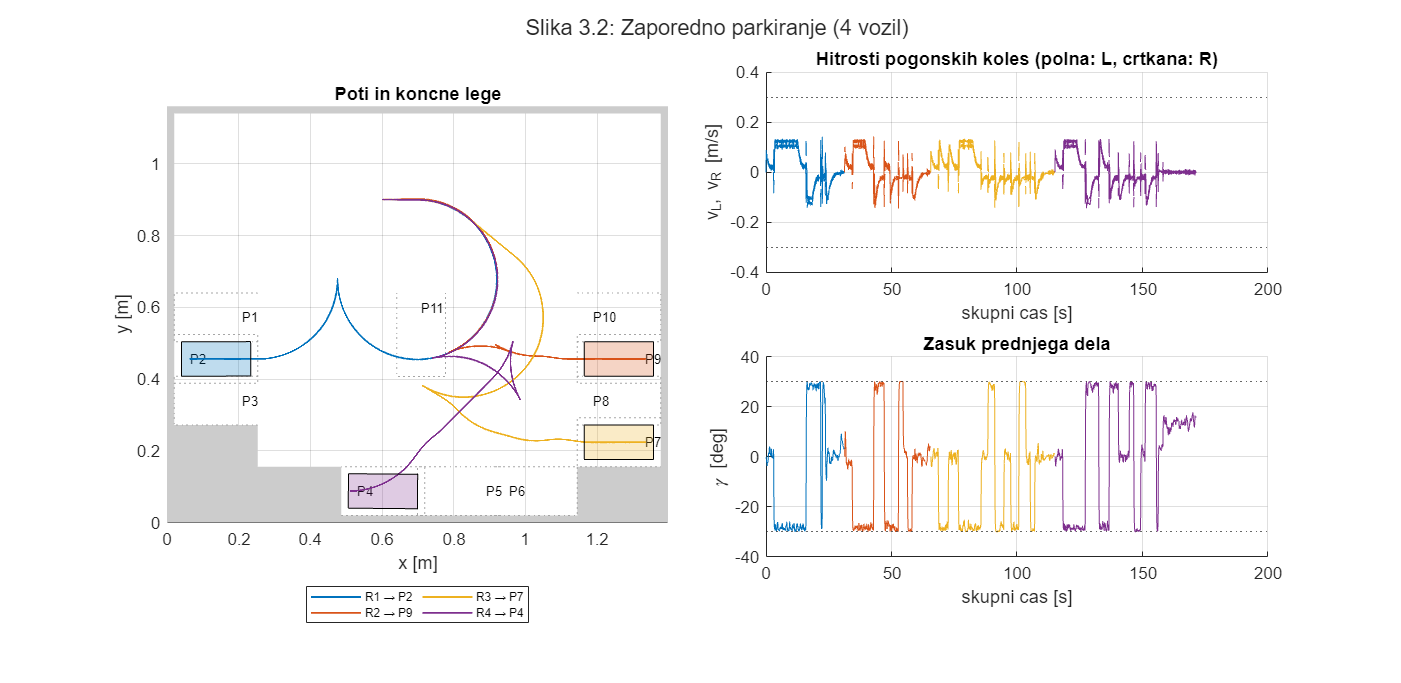

Tabela 3.2: rezultati parkiranja
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       2       31.3    1.6969    0.45393     0.13835    0.14489         1         0  
      2       9      34.29     1.348    0.71818    0.098514    0.14485         1         0  
      3       7      49.54    1.7486    0.48381    0.037366    0.14197         1         0  
      4       4      56.53    1.8623    0.11417     0.43233    0.14338         1         0  



prikaziPrimer('ex3case2.mat', true, '3.2', ...
    'Zaporedno parkiranje (4 vozil)');

### 3.3 S → P1, P3, P10, P8, P6, P2, P7, P9, P4, P5

Slika 3.3: pot, končne lege in vhodi. Tabela 3.3: rezultati vozil. Seme rng = 303.

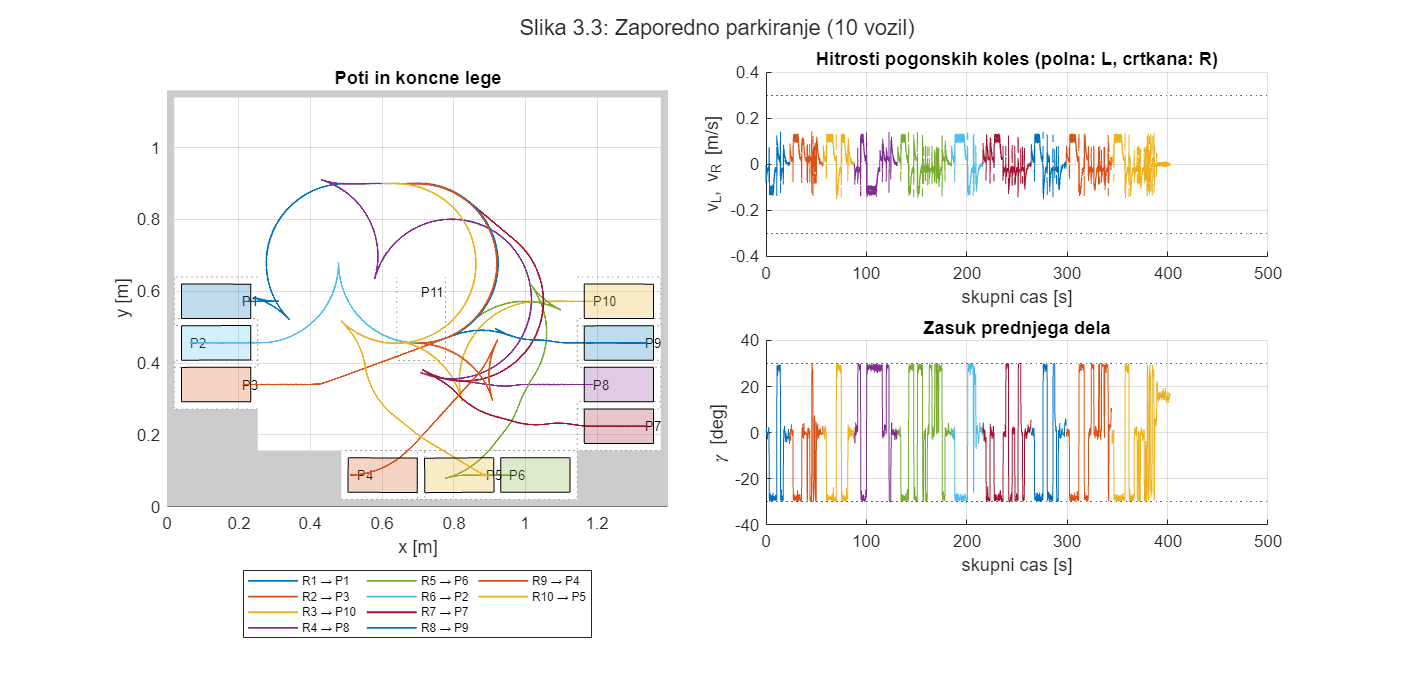

Tabela 3.3: rezultati parkiranja
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1        1     23.82    0.9049     0.5272     0.06441    0.14116         1         0  
      2        3     33.18     1.344    0.76136    0.041382    0.14309         1         0  
      3       10     31.25    1.6523    0.67746    0.046145    0.15202         1         0  
      4        8     42.89    2.0755    0.75264    0.032091    0.14325         1         0  
      5        6     53.67    1.8472    0.56215    0.076955    0.14508         1         0  
      6        2     31.26    1.7006    0.70738     0.12239    0.13808         1         0  
      7        7     48.14    1.7502    0.54209    0.051535    0.14296         1         0  
      8        9     34.92    1.3494    0.49397     0.15906    0.15239         1         0  
      9        4     45.37    1.8479

prikaziPrimer('ex3case3.mat', true, '3.3', ...
    'Zaporedno parkiranje (10 vozil)');

### 3.4 S → P11, P1, P2, P9, P10, P5, P3, P8, P7, P4, P6

Slika 3.4: pot, končne lege in vhodi. Tabela 3.4: rezultati vozil. Seme rng = 304.

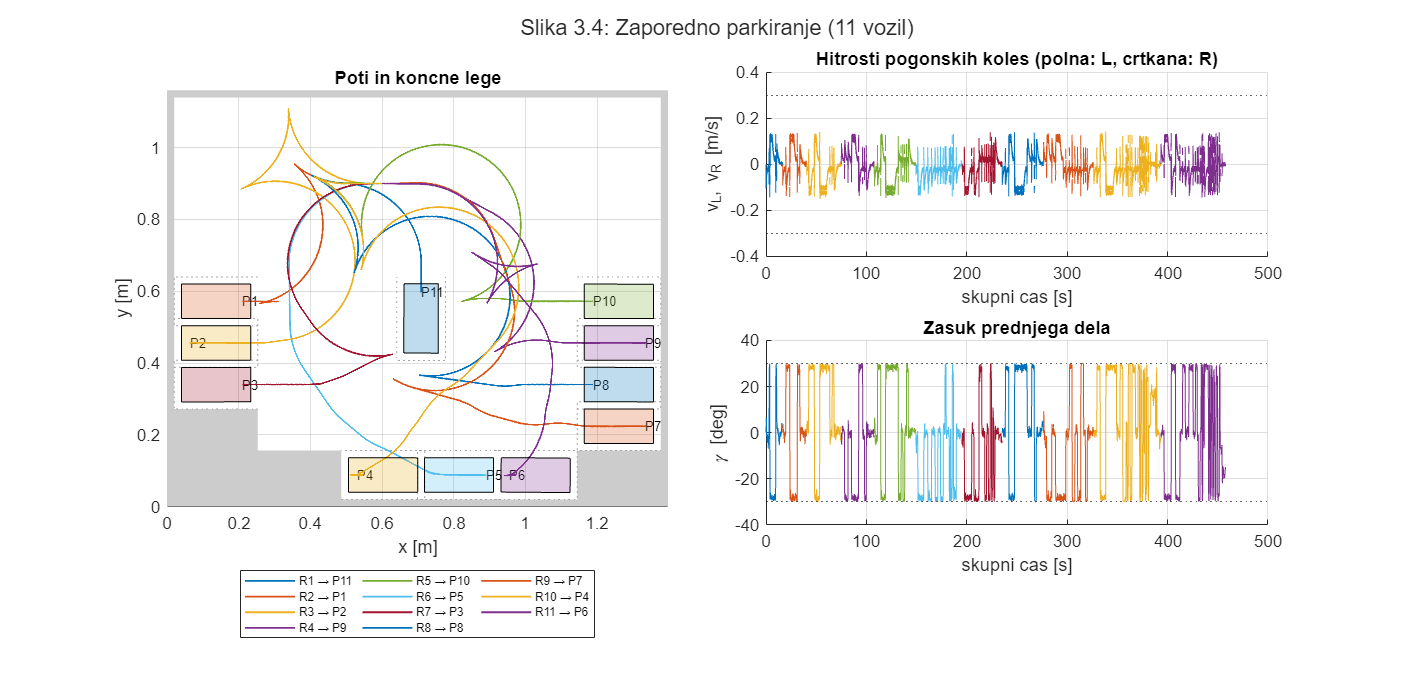

Tabela 3.4: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1       11     16.61    0.55698    0.68343     0.10771    0.14377         1         0  
      2        1     23.94    0.90508    0.44019    0.031445    0.14206         1         0  
      3        2     34.49     1.6803     0.5767    0.012512    0.15028         1         0  
      4        9     32.86     1.2206    0.59167    0.055319    0.14196         1         0  
      5       10     41.45     1.8092    0.45083    0.069379    0.15187         1         0  
      6        5     46.25     1.3424    0.70455    0.059303    0.13991         1         0  
      7        3     39.72     1.3006    0.55573     0.10711    0.14338         1         0  
      8        8        41     2.0182     0.5672     0.12036    0.13952         1         0  
      9        7     50.15

prikaziPrimer('ex3case4.mat', true, '3.4', ...
    'Zaporedno parkiranje (11 vozil)');

### 3.5 Naključne začetne lege in zaporedje vseh 11 ciljev

Slika 3.5: pot, končne lege in vhodi. Tabela 3.5: rezultati vozil. Seme rng = 601.

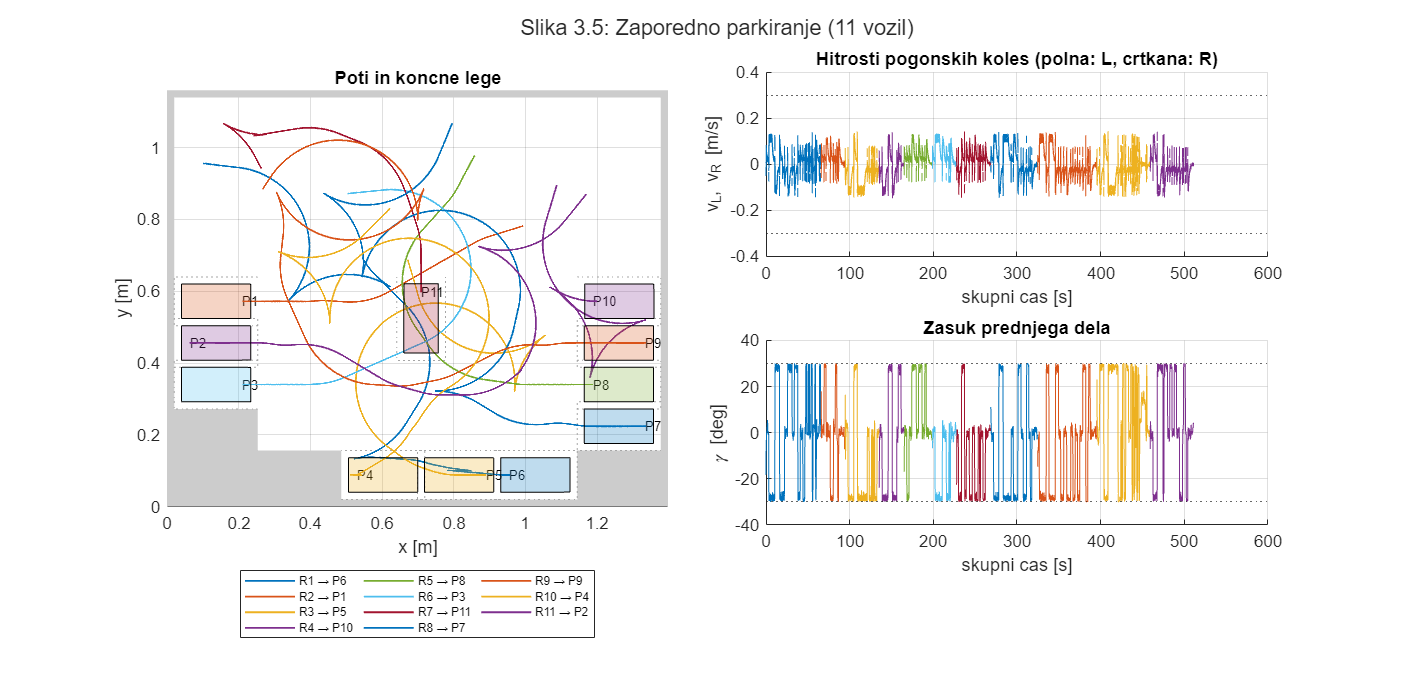

Tabela 3.5: rezultati parkiranja
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg     vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    _________    ________    _________    ____

      1        6     66.05     2.2942    0.64095      0.13196    0.14278         1         0  
      2        1     28.58    0.83314    0.36871     0.027573    0.12336         1         0  
      3        5     40.77     1.9433    0.27268     0.075125     0.1447         1         0  
      4       10     29.68     1.2592    0.63424     0.073797    0.14807         1         0  
      5        8      33.8     1.1006    0.45389     0.030704    0.13107         1         0  
      6        3     28.94     1.2577     0.5743     0.080987    0.13295         1         0  
      7       11     40.93     1.1092    0.66252     0.032397    0.14501         1         0  
      8        7     55.95     2.4287    0.62821    0.0014007    0.14497         1         0  
      9        9

prikaziPrimer('ex3random1.mat', true, '3.5', ...
    'Zaporedno parkiranje (11 vozil)');

Uspešnih je vseh 41 parkiranj brez zaznanih trkov. Največji napaki sta 0,761 mm in 0,447°; najdaljše parkiranje traja 70,82 s. Zahtevi natančnosti in omejitvi koles sta izpolnjeni. Zasuk γ v vseh primerih ostane znotraj ±30°.

## 4. Skupni rezultat in omejitve

Vseh 90 parkiranj v 18 primerih je uspešnih. Največja položajna napaka je 0,763 mm, kotna pa 0,4475°. Posamezno parkiranje traja največ 70,82 s, torej manj od dovoljene omejitve 120 s.

Pri več vozilih je pot odvisna od zasedenosti. Omejitev zasuka zahteva dodatne manevre, ustavljanje med odseki pa podaljša vožnjo. Uteženi A* ne zagotavlja najkrajše poti; gostejše iskanje ob parkirišču poveča računsko zahtevnost. Preizkusi z izbranimi semeni niso dokaz uspeha pri vsaki realizaciji šuma.

Vseh 18 primerov je bilo ločeno preverjenih tudi z originalnima simParking in simParkingLim. Pri nalogah 1 in 2 se primerjani zapisi povsem ujemajo; pri nalogi 3 so razlike koordinat poti le reda 10⁻¹⁶ m. Časi in zapisi trkov se ujemajo. Spodaj je iz shranjenega neposrednega preizkusa dodatno preverjen primer A → P11.

izvirni = load('originalSimulatorCheck.mat', 'data');
numericni = load('ex1case1.mat', 'data');
assert(norm(izvirni.data.qEnd-numericni.data.qEnd) < 1e-8);
assert(isequal(izvirni.data.vl, numericni.data.vl));
assert(isequal(izvirni.data.c, numericni.data.c));
disp('Primer A → P11: numerični in originalni simulator se ujemata.');

Primer A → P11: numerični in originalni simulator se ujemata.


## 5. Uporabljene datoteke

Rešitev sestavljajo controlParking.m, controlParkingLim.m, parkingControl.m in parkingPlan.m. Za prikaz poročilo uporablja parkingResults.m, ki potrebuje Map.m in wrapToPi.m. Podatki so bili izračunani z runParkingCase.m in testParking.m ter shranjeni s store.m; uporabljeni so izvirni updateVehicle.m, derivKinematics.m in VehicleConstraints.m. Originalni preverjanji uporabljata simParking.m in simParkingLim.m.

Rezultati poročila: ex1case1.mat–ex1case7.mat, ex1random1.mat, ex2case1.mat–ex2case4.mat, ex2random1.mat, ex3case1.mat–ex3case4.mat, ex3random1.mat ter originalSimulatorCheck.mat. Vse datoteke naj bodo v isti mapi kot homework.mlx. Gradivo predavanj je navedeno pri opisu metode; za ponovno izrisovanje ni potrebno.

### Pomožna funkcija za prikaz

Lokalna funkcija poenoti izris vseh primerov in ne spreminja regulatorja ali podatkov.

function prikaziPrimer(datoteka, limited, oznaka, naslov)
S = load(datoteka, 'data');
T = parkingResults(S.data, limited);
sgtitle(['Slika ', oznaka, ': ', naslov], 'Interpreter', 'none');
ax = findobj(gcf, 'Type', 'Axes');
ax = ax(arrayfun(@(a) strcmp(a.Title.String, ...
    'Poti in koncne lege'), ax));
h = flipud(findobj(ax, 'Type', 'Line', 'LineWidth', 1.1));
labels = compose('R%d → P%d', T.robot, T.cilj);
legend(ax, h, labels, 'Location', 'southoutside', ...
    'NumColumns', 3, 'FontSize', 7);
disp(['Tabela ', oznaka, ': rezultati parkiranja']);
disp(T)
end